filename = 'Servo_Latency_Response_Data.xlsx'; 

% --- Load data ---
T = readtable(filename);

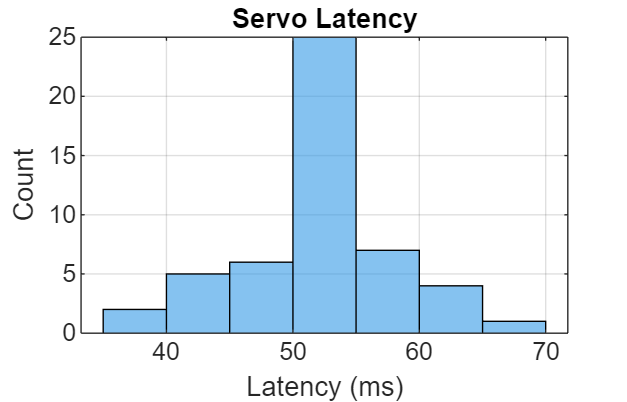

vn = matlab.lang.makeValidName(T.Properties.VariableNames);
T.Properties.VariableNames = vn;

% Find latency column
latCol = vn{contains(lower(vn),'latency')};
Latency = T.(latCol);

% Keep valid numbers
Latency = Latency(~isnan(Latency));

% --- Plot histogram ---
figure('Color','w','Position',[600 600 2100 1350])
histogram(Latency, 'BinMethod','sturges', 'FaceColor',[0.2 0.6 0.9], 'EdgeColor','k');
xlabel('Latency (ms)');
ylabel('Count');
title('Servo Latency');
grid on; box on;